# **RS-WISP-06-06: Glideslope Transfer Config**

**WoerkerInSpace**

**Hongseok Kim**

**2/24/2025**

addpath('C:\Users\user\Desktop\Redstone_WISP\RS_WISP_05_RPOD_Functions')

## V. Matlab Function Test

clear; clc;
%% Input Parameters

% Target Information
Target.a = 6880.403000000002;
Target.e = 0.0005886;
Target.i = 97.3729;
Target.RAAN = 302.4312;
Target.AOP = 49.74169999995479;
Target.TA = 310.4333000000452;



% Chaser Information
Chaser.a = 6880.403000000002;
Chaser.e = 0.0005886;
Chaser.i = 97.3729;
Chaser.RAAN = 302.4312;
Chaser.AOP = 49.74169999995479;
Chaser.TA = 310;

% Timing of Docking
t_f = 28800;

%% Main Algorithm

% Change to ECI frame

% rv data of the target wrt ECI
[r_target, v_target] = kepler2ijk_hs(Target.a, Target.e, Target.i, Target.RAAN, Target.AOP, Target.TA);

% rc data of the chaser wrt ECI
[r_chaser, v_chaser] = kepler2ijk_hs(Chaser.a, Chaser.e, Chaser.i, Chaser.RAAN, Chaser.AOP, Chaser.TA);


rho_vec_T = [0;-1;0];
rho_dot_0 = -0.1;
rho_dot_T = -0.001;
N = 5;

 [T, time_vector, Delta_t, Delta_v_m_LVLH_mat, Delta_r_m_LVLH_mat ,delta_r_t_mat, delta_v_t_mat, rho_t_mat, rho_dot_t_mat, delta_v_m_plus_mat] = glideslope_transfer(r_target, v_target, r_chaser, v_chaser, rho_vec_T, rho_dot_0, rho_dot_T, N)

T = 2.3730e+03

time_vector = 1.0e+03 *

         0
    0.0048
    0.0096
    0.0144
    0.0192
    0.0240
    0.0288
    0.0336
    0.0384
    0.0431


Delta_t = 474.5944

Delta_v_m_LVLH_mat =    -0.0318    0.0599    0.0000
   -0.0449   -0.0358   -0.0000
   -0.0179   -0.0142   -0.0000
   -0.0071   -0.0057   -0.0000
   -0.0028   -0.0023   -0.0000


Delta_r_m_LVLH_mat =    -0.0679  -20.9984   -0.0000
   -0.0260   -8.6514   -0.0000
   -0.0093   -3.7359   -0.0000
   -0.0026   -1.7790   -0.0000
   -0.0000   -1.0000   -0.0000


delta_r_t_mat =    -0.1733  -52.0129   -0.0000
   -0.3242  -51.7252   -0.0000
   -0.4721  -51.4360   -0.0000
   -0.6169  -51.1452   -0.0000
   -0.7587  -50.8529   -0.0000
   -0.8974  -50.5591   -0.0000
   -1.0331  -50.2639   -0.0000
   -1.1657  -49.9672   -0.0000
   -1.2953  -49.6691   -0.0000
   -1.4218  -49.3697   -0.0000


delta_v_t_mat =    -0.0318    0.0598    0.0000
   -0.0312    0.0602    0.0000
   -0.0305    0.0605    0.0000
   -0.0299    0.0608    0.0000
   -0.0293    0.0611    0.0000
   -0.0286    0.0614    0.0000
   -0.0280    0.0617    0.0000
   -0.0273    0.0620    0.0000
   -0.0267    0.0623    0.0000
   -0.0261    0.0626    0.0000


rho_t_mat =    -0.1733  -51.0129   -0.0000
   -0.1653  -48.6708   -0.0000
   -0.1578  -46.4352   -0.0000
   -0.1505  -44.3013   -0.0000
   -0.1436  -42.2643   -0.0000
   -0.1370  -40.3199   -0.0000
   -0.1307  -38.4639   -0.0000
   -0.1247  -36.6922   -0.0000
   -0.1189  -35.0011   -0.0000
   -0.1134  -33.3868   -0.0000


rho_dot_t_mat =     0.0003    0.1000    0.0000
    0.0003    0.0955    0.0000
    0.0003    0.0911    0.0000
    0.0003    0.0870    0.0000
    0.0003    0.0830    0.0000
    0.0003    0.0792    0.0000
    0.0003    0.0756    0.0000
    0.0002    0.0722    0.0000
    0.0002    0.0689    0.0000
    0.0002    0.0658    0.0000


delta_v_m_plus_mat =    -0.0318    0.0598    0.0000
   -0.0127    0.0238    0.0000
   -0.0050    0.0095    0.0000
   -0.0020    0.0038    0.0000
   -0.0008    0.0015    0.0000


 total_elapsed_time = T/3600

total_elapsed_time = 0.6592

### IV.1 Data Display

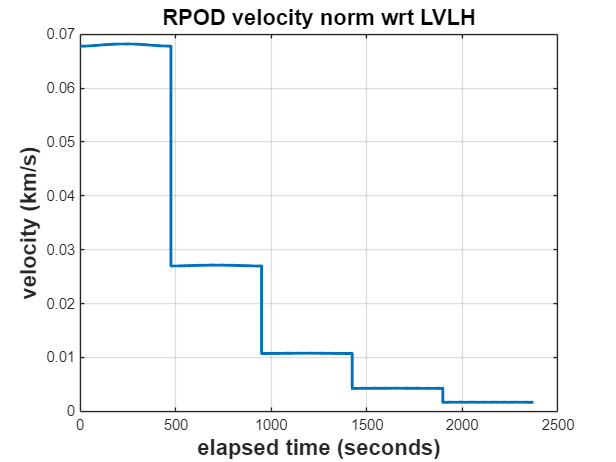


delta_v_t_norm = zeros(length(time_vector),1);

for i = 1:length(time_vector)
  delta_v_t_norm(i) = norm(delta_v_t_mat(i,:));
end

figure;
plot(time_vector, delta_v_t_norm,'LineWidth',2)
title('RPOD velocity norm wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
ylabel('velocity (km/s)','FontSize',15,'FontWeight','bold')
grid on

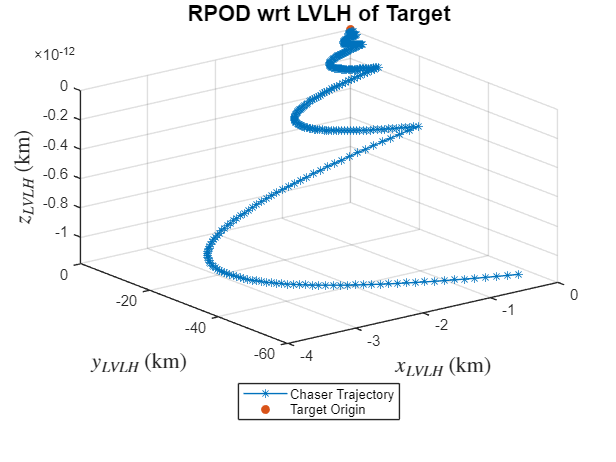



figure;
plot3(delta_r_t_mat(:,1),delta_r_t_mat(:,2),delta_r_t_mat(:,3),'*-')
hold on
scatter3(0,0,0,'filled','o')
hold off
grid on
title('RPOD wrt LVLH of Target','FontSize',15,'FontWeight','bold')
xlabel('$x_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
ylabel('$y_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
zlabel('$z_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
legend('Chaser Trajectory', 'Target Origin','Location','southoutside')

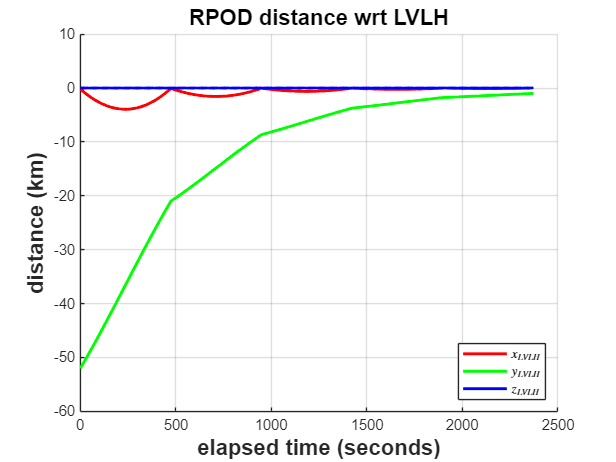




figure;
hold on
plot(time_vector, delta_r_t_mat(:,1),'r','LineWidth',2)
plot(time_vector, delta_r_t_mat(:,2),'g','LineWidth',2)
plot(time_vector, delta_r_t_mat(:,3),'b','LineWidth',2)
hold off
title('RPOD distance wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
ylabel('distance (km)','FontSize',15,'FontWeight','bold')
legend('$x_{LVLH}$','$y_{LVLH}$','$z_{LVLH}$', 'Interpreter', 'latex','Location','southeast')
grid on

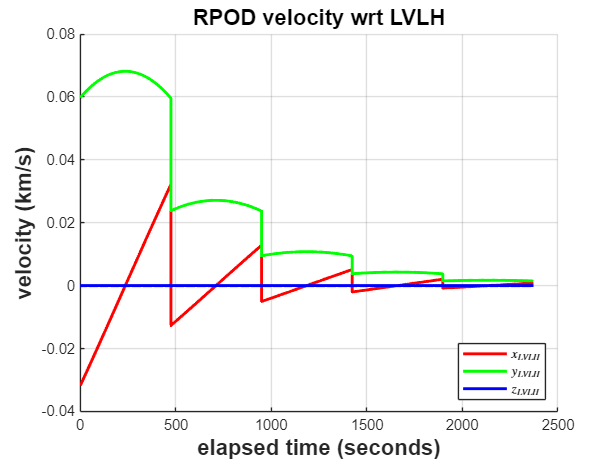





figure;
hold on
plot(time_vector, delta_v_t_mat(:,1),'r','LineWidth',2)
plot(time_vector, delta_v_t_mat(:,2),'g','LineWidth',2)
plot(time_vector, delta_v_t_mat(:,3),'b','LineWidth',2)
hold off
title('RPOD velocity wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
ylabel('velocity (km/s)','FontSize',15,'FontWeight','bold')
legend('$x_{LVLH}$','$y_{LVLH}$','$z_{LVLH}$', 'Interpreter', 'latex','Location','southeast')
grid on

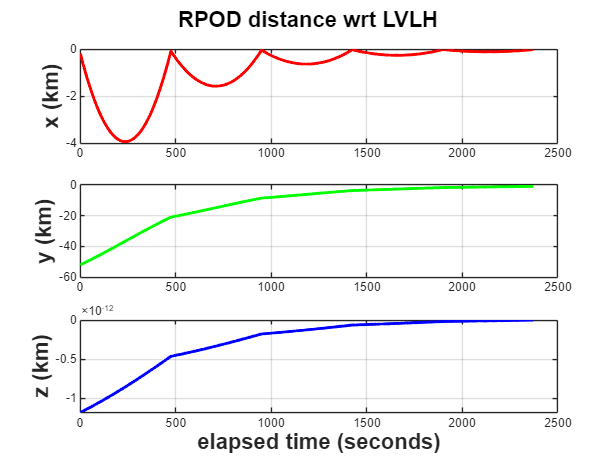




figure;
subplot(3,1,1)
plot(time_vector, delta_r_t_mat(:,1),'r','LineWidth',2)
ylabel('x (km)','FontSize',15,'FontWeight','bold')
grid on
subplot(3,1,2)
plot(time_vector, delta_r_t_mat(:,2),'g','LineWidth',2)
ylabel('y (km)','FontSize',15,'FontWeight','bold')
grid on
subplot(3,1,3)
plot(time_vector, delta_r_t_mat(:,3),'b','LineWidth',2)
ylabel('z (km)','FontSize',15,'FontWeight','bold')
sgtitle('RPOD distance wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
grid on

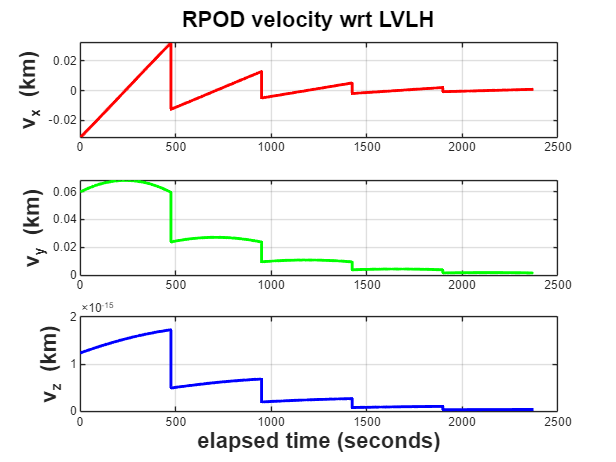



figure;
subplot(3,1,1)
plot(time_vector, delta_v_t_mat(:,1),'r','LineWidth',2)
ylabel('v_x (km)','FontSize',15,'FontWeight','bold')
grid on
subplot(3,1,2)
plot(time_vector, delta_v_t_mat(:,2),'g','LineWidth',2)
ylabel('v_y (km)','FontSize',15,'FontWeight','bold')
grid on
subplot(3,1,3)
plot(time_vector, delta_v_t_mat(:,3),'b','LineWidth',2)
ylabel('v_z (km)','FontSize',15,'FontWeight','bold')
sgtitle('RPOD velocity wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
grid on